## Pole/Zero Filter

function filtered_signal = zero_pole_filter(poles, zeros, gain, signal, t)
    [validPoles, validZeros] = validatePolesZeros(poles, zeros)
    [b, a] = zp2tf(validZeros, validPoles, gain);
    
    filtered_signal = filter(b, a, signal);
    
    figure;
    subplot(2, 1, 1);
    plot(t, signal);
    title('Original Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    subplot(2, 1, 2);
    plot(t, filtered_signal);
    title('Filtered Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    figure;
    freqz(b, a);
    title('Filter Frequency Response');
end

function [validPoles, validZeros] = validatePolesZeros(poles, zeros)
    validPoles = poles;
    validZeros = zeros;

    for i = 1:length(poles)
        if abs(poles(i)) >= 1
            validPoles(i) = poles(i) / abs(poles(i)) * 0.99;
            disp('Warning: A pole was adjusted to ensure stability.');
        end
    end

    for i = 1:length(zeros)
        if abs(zeros(i)) > 2 
            validZeros(i) = zeros(i) / abs(zeros(i)) * 2; 
            disp('Warning: A zero was adjusted to meet design constraints.');
        end
    end
end

validPoles =    0.9000 - 0.1000i
   0.9000 + 0.1000i


validZeros =    0.5000 - 0.5000i
   0.5000 + 0.5000i


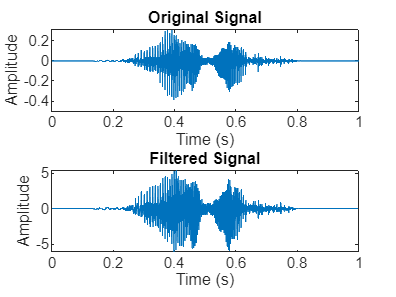

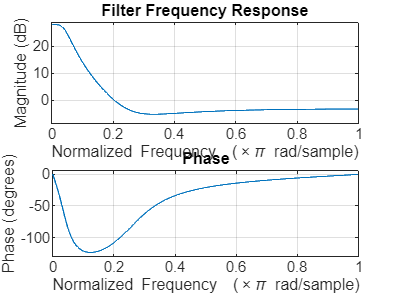

filtered_signal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% Random poles and zeros
zeros = [0.5+0.5i, 0.5-0.5i]';
poles = [0.9+0.1i, 0.9-0.1i]';
gain = 1;

fs = 44100;
T = 1;
t= (0:1/fs:T)';

recorded_signal = audioread("hello_there.wav");
recorded_signal=recorded_signal(1:length(t));

filtered_signal = zero_pole_filter(poles, zeros, gain, recorded_signal, t)

sound(recorded_signal, fs);
pause(2);
sound(filtered_signal, fs);

## 12 Band Equalizer

function output_signal = equalizer(input_signal, gains, bands, t)
    fs = 44100; 
    nyquist = fs / 2;
    output_signal = zeros(size(input_signal));
    
    for i = 1:12

        if i == 1
            low_cutoff = max(1, bands(i) / sqrt(2)); % Ensure > 0 Hz
        else
            low_cutoff = max(1, bands(i-1) * sqrt(2)); % Ensure > 0 Hz
        end
        
        if i == 12
            high_cutoff = min(nyquist - 1, bands(i) * sqrt(2)); % Ensure < Nyquist
        else
            high_cutoff = min(nyquist - 1, bands(i+1) / sqrt(2)); % Ensure < Nyquist
        end
        
        Wn = [low_cutoff, high_cutoff] / nyquist;
        
        % Design a band-pass filter
        if any(Wn <= 0) || any(Wn >= 1)
            continue;
        end
        [b, a] = butter(2, Wn, 'bandpass');
        
        % Filter the signal and apply the gain
        filtered_band = filter(b, a, input_signal);
        band_gain = 10^(gains(i) / 20); % Convert dB to linear scale
        filtered_band = band_gain * filtered_band;
        
        % Add the contribution to the output signal
        output_signal = output_signal + filtered_band;
    end

    figure;
    subplot(2, 1, 1);
    plot(t, input_signal);
    title('Original Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    subplot(2, 1, 2);
    plot(t, output_signal);
    title('Equalized Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    

    figure;
    hold on;
    for i = 1:12
        if i == 1
            low_cutoff = bands(i) / sqrt(2);
        else
            low_cutoff = bands(i-1) * sqrt(2);
        end
        if i == 12
            high_cutoff = bands(i) * sqrt(2);
        else
            high_cutoff = bands(i+1) / sqrt(2);
        end
        Wn = [low_cutoff, high_cutoff] / nyquist;
        if any(Wn <= 0) || any(Wn >= 1)
            continue; % Skip invalid bands
        end
        [b, a] = butter(2, Wn, 'bandpass');
        [h, f] = freqz(b, a, 1024, fs);
        h = h * 10^(gains(i) / 20);
        plot(f, abs(h));
    end
    title('Frequency Responses of the 12 Bands');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    legend(arrayfun(@(x) sprintf('%d Hz', x), bands, 'UniformOutput', false), 'Location', 'Best');
    grid on;
end

clc; clear; close all;
fs = 44100; 
bands = [63, 125, 250, 400, 630, 1000, 1600, 2500, 4000, 6300, 10000, 16000];
num_bands = length(bands);
gains = [-6,7,3,-6,-1,-9,3,-10,6,6,3,10]

gains =     -6     7     3    -6    -1    -9     3   -10     6     6     3    10


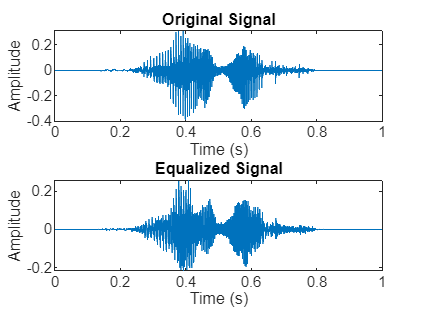

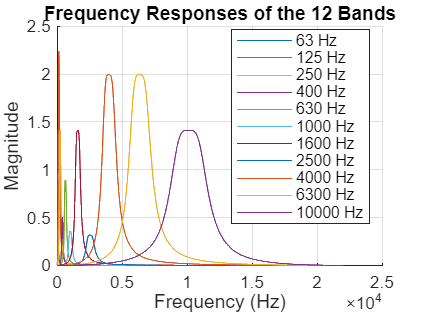

audio_eq =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


t = 0:1/fs:1;

recorded_signal = audioread("hello_there.wav");
recorded_signal=recorded_signal(1:length(t));
audio_eq = equalizer(recorded_signal, gains, bands, t)

sound(recorded_signal, fs);
pause(2);
sound(audio_eq, fs);

## Echo Effect Controller

function output_signal = echo_delay(input_signal, num_echoes, min_delay, max_delay, decay_factor, fs, t)
    
    output_signal = input_signal;
    for i = 1:num_echoes
        % Calculate the delay for this echo
        delay_time = min_delay + (max_delay - min_delay) * (i / num_echoes);
        delay_samples = round(delay_time * fs); 
        
        
        delayed_signal = [zeros(1, delay_samples), input_signal]; 
        delayed_signal = delayed_signal(1:length(input_signal)); 
        
        
        output_signal = output_signal + decay_factor^i * delayed_signal;
    end

    figure;
    subplot(2, 1, 1);
    plot(t, input_signal);
    title('Original Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    subplot(2, 1, 2);
    plot(t, output_signal);
    title('Signal with Echo Effect');
    xlabel('Time (s)');
    ylabel('Amplitude')
        
end 

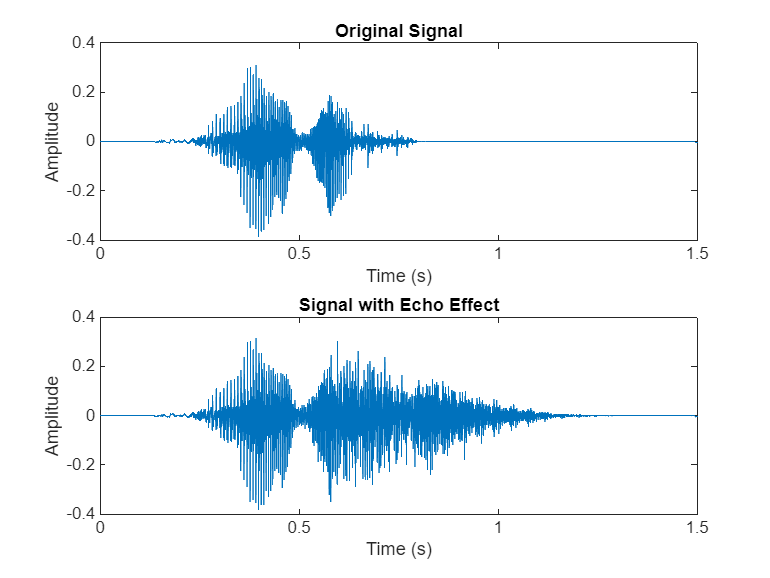

fs = 44100; 
t = 0:1/fs:1.5; 

max_delay = 0.5; 
min_delay = 0.2; 
num_echoes = 7; 
decay = 0.7;

input_signal = audioread("hello_there.wav");
input_signal=input_signal(1:length(t));

output_signal = echo_delay(input_signal, num_echoes, min_delay, max_delay, decay, fs, t);


sound(input_signal, fs);
pause(2);
sound(output_signal, fs);